clc; clear;
L = 0.1; Tl = 50; Tr = 100; k = 80; q = 4e+5; N = 15;

% Create tridiagonal matrix columns
f = -2 * ones(N,1);
e = ones(N,1); e(1) = 0;
g = ones(N,1); g(N) = 0;

% Create right-hand side vector
dx = 2* L / (N +1);
r = - q * dx^2 / k * ones(N,1);
r(1) = r(1) - Tl; r(N) = r(N) - Tr;

% Create a tridiagonal full matrix
A = create_array(N);

i_guess = (Tr + Tl) / 2 *ones(N, 1);

sol = linsolve(A, r)

sol =    58.9844
   67.1875
   74.6094
   81.2500
   87.1094
   92.1875
   96.4844
  100.0000
  102.7344
  104.6875


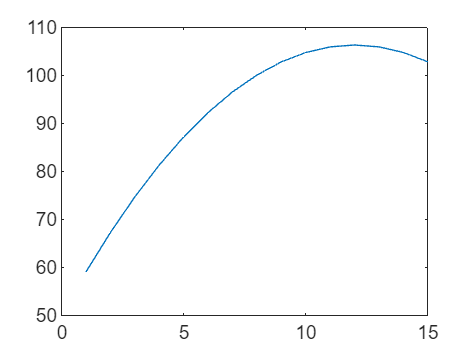

plot(sol)

function A = create_array(n)
    A = -2*eye(n);
    for i = 1:n-1
        A(i,i+1) = 1;
        A(i+1,i) = 1;
    end
end
